clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder1 = 'D:\Profile\qse\Files\_EDMRoC pinSC\20210617';
load([Opt.LFolder1, '\cwEDMR_2021_06_17.mat']);

#### Fit

% Dangling Bond
Sys.S = 1/2;
% Sys.g = [2.0079 2.0061 2.0034];% Value from Jannik
Sys.g = 2.0055;
% Sys.A = [151 269]; % MHz
% Sys.lw = [0.7522 1.0291]; % mT [Gaussian Lorentzian]
Sys.lw = [0.7522 1.0291];
% Sys.Nucs = 'Si';
Sys.FieldOffset = -1;

% Vary.g = [0.01, 0.01, 0.01];
Vary.lw = [0.4 0.4];
% Vary.A = [50 50];
Vary.FieldOffset = 3;

Exp.mwFreq = 9.6055875; % GHz
icw = 1;
Exp.Range = [min(x(:, icw)) max(x(:, icw))];

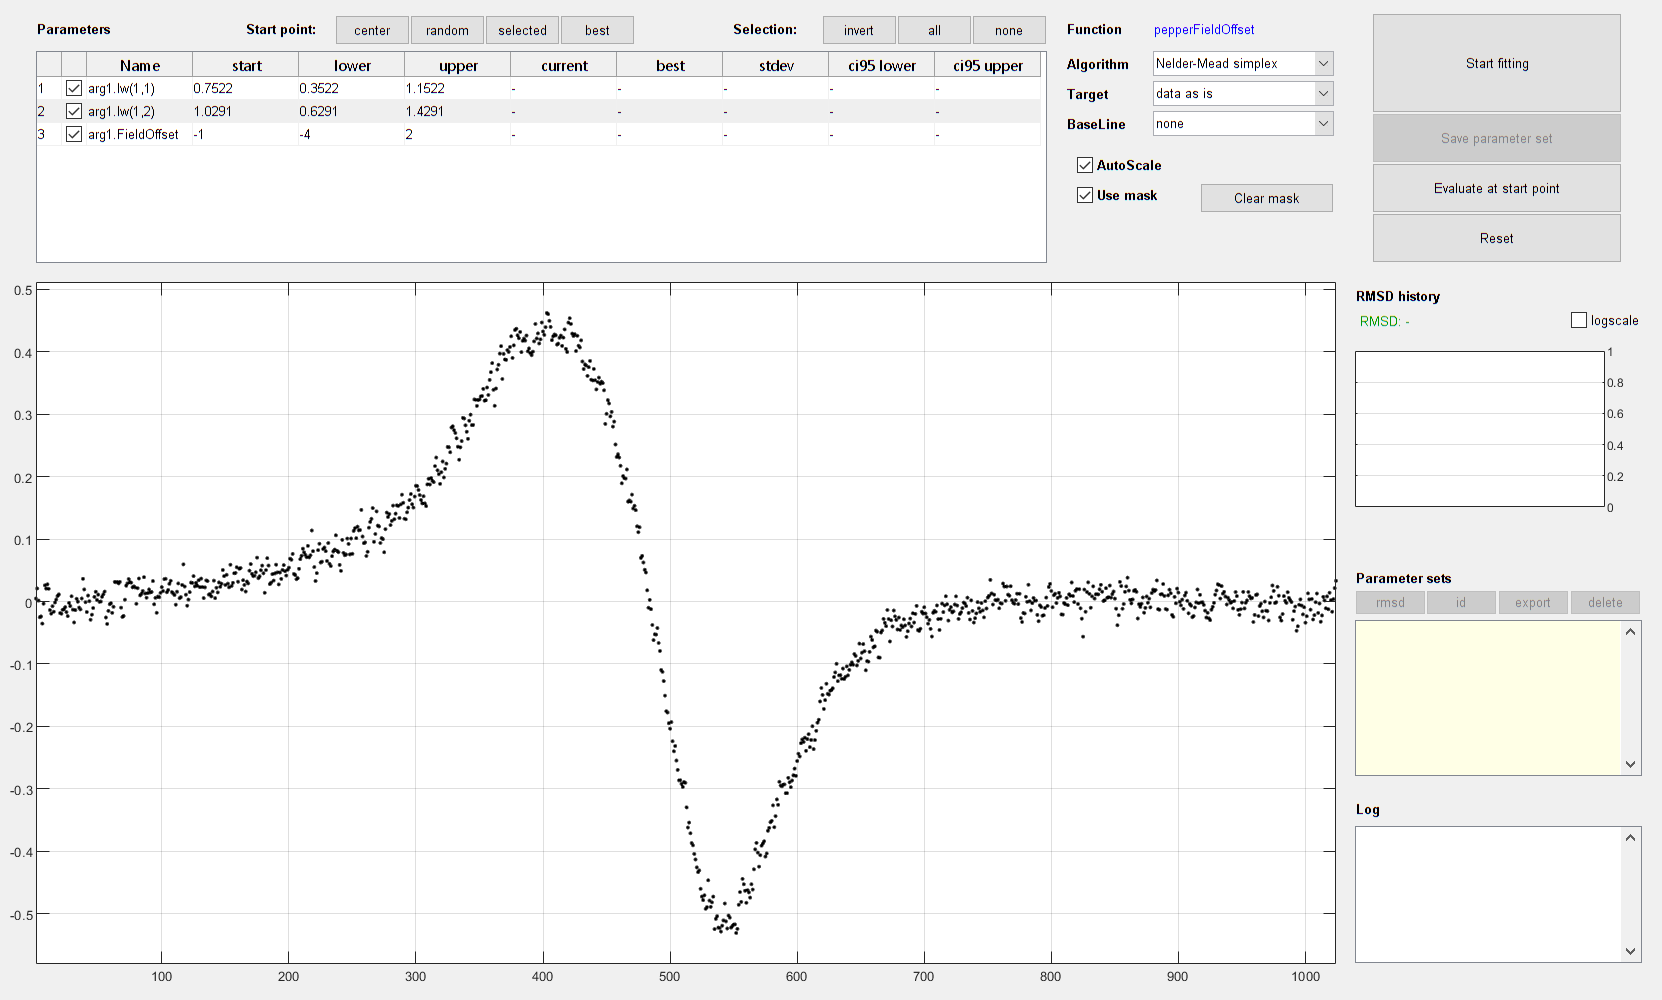

esfit(y(:, icw), @pepperFieldOffset, {Sys, Exp}, {Vary})